% Step 1: Define DCT and IDCT functions
function result = dct_2d(block)
    result = dct2(block);
end

function result = idct_2d(block)
    result = idct2(block);
end

% Step 2: Quantize and dequantize functions
function result = quantize(block, quant_matrix)
    result = round(block ./ quant_matrix);
end

function result = dequantize(block, quant_matrix)
    result = block .* quant_matrix;
end

% Step 3: Block processing functions
function blocks = divide_into_blocks(image, block_size)
    [h, w] = size(image);
    blocks = mat2cell(image, repmat(block_size, h/block_size, 1), repmat(block_size, w/block_size, 1));
end

function image = combine_blocks(blocks)
    image = cell2mat(blocks);
end

% Step 4: Encoding and decoding functions
function compressed_image = encode_image(image, quant_matrix)
    image = double(image) - 128; % Level shift
    blocks = divide_into_blocks(image, 8);
    dct_blocks = cellfun(@dct_2d, blocks, 'UniformOutput', false);
    quantized_blocks = cellfun(@(block) quantize(block, quant_matrix), dct_blocks, 'UniformOutput', false);
    compressed_image = combine_blocks(quantized_blocks);
end

function reconstructed_image = decode_image(compressed_image, quant_matrix)
    blocks = divide_into_blocks(compressed_image, 8);
    dequantized_blocks = cellfun(@(block) dequantize(block, quant_matrix), blocks, 'UniformOutput', false);
    idct_blocks = cellfun(@idct_2d, dequantized_blocks, 'UniformOutput', false);
    reconstructed_image = combine_blocks(idct_blocks) + 128; % Level shift back
    reconstructed_image = uint8(max(min(reconstructed_image, 255), 0));
end

% Step 5: PSNR calculation
function result = psnr(original, reconstructed)
    mse = mean((double(original(:)) - double(reconstructed(:))).^2);
    if mse == 0
        result = Inf;
    else
        result = 20 * log10(255 / sqrt(mse));
    end
end

% Step 6: Visualization function
function display_images(original, compressed, reconstructed)
    figure;
    subplot(1, 3, 1);
    imshow(original, []);
    title('Original Image');
    
    subplot(1, 3, 2);
    imshow(compressed, []);
    title('Compressed Coefficients');
    
    subplot(1, 3, 3);
    imshow(reconstructed, []);
    title('Reconstructed Image');
end

% Main script
% Define the quantization matrix
QUANTIZATION_MATRIX = [
    16, 11, 10, 16, 24, 40, 51, 61;
    12, 12, 14, 19, 26, 58, 60, 55;
    14, 13, 16, 24, 40, 57, 69, 56;
    14, 17, 22, 29, 51, 87, 80, 62;
    18, 22, 37, 56, 68, 109, 103, 77;
    24, 35, 55, 64, 81, 104, 113, 92;
    49, 64, 78, 87, 103, 121, 120, 101;
    72, 92, 95, 98, 112, 100, 103, 99
];

% Load the image
image_path = 'example.jpg'; 
original_image = imread(image_path);
if size(original_image, 3) == 3
    original_image = rgb2gray(original_image);
end

% Encode the image
compressed_image = encode_image(original_image, QUANTIZATION_MATRIX);

% Decode the image
reconstructed_image = decode_image(compressed_image, QUANTIZATION_MATRIX);

% Evaluate the quality
quality = psnr(original_image, reconstructed_image);
disp(['PSNR between original and reconstructed image: ', num2str(quality), ' dB']);

PSNR between original and reconstructed image: 35.8081 dB


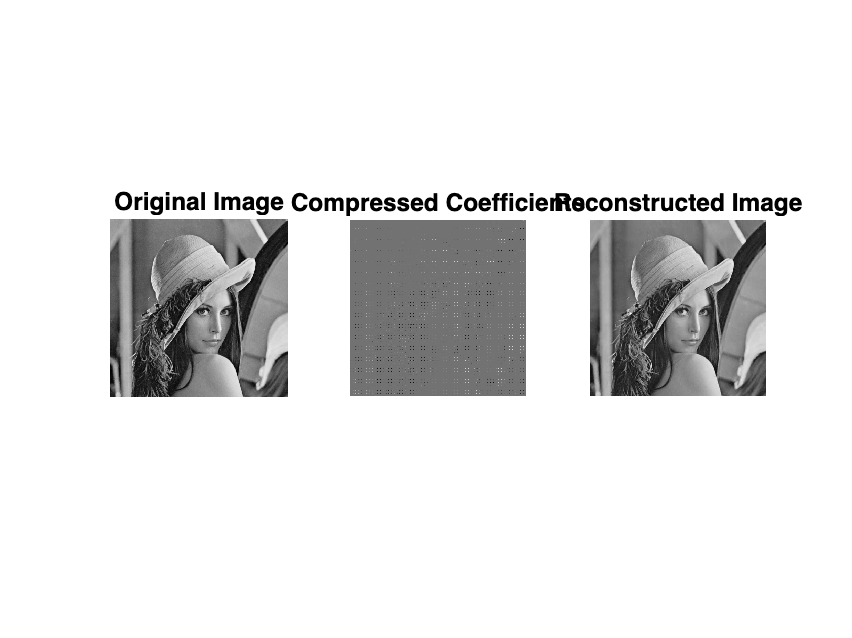


% Display the images
display_images(original_image, compressed_image, reconstructed_image);


% Save the reconstructed image
imwrite(reconstructed_image, 'reconstructed_image.jpg');
disp('Reconstructed image saved as "reconstructed_image.jpg"');

Reconstructed image saved as "reconstructed_image.jpg"
